# 车辆通信仿真

## 预处理

clc,clear,clf;

## 情景设置

% 获取车辆行驶场景
[allData, scenario, sensor] = car_scenario_file();
% designer_handle = drivingScenarioDesigner("car_scenario_file.mat");

## 信号设计

M = 64;                             % Delay轴(时域符号数)
N = 256;                            % Doppler轴(子载波数量)
df = 50e3;                          % 频率箱的间隔(Hz),与LTE系统的子载波间隔相同，即频谱分辨率
fc = 5.9e9;                         % 载频(5.9GHz,遵循IEEE 802.11p标准)
mod_level = 16;                     % M-QAM阶调制
ofdm_subframe_num = M;              % OFDM子符号数
k_bit = log2(mod_level);            % 每符号比特数
pad_len = 10;                       % 填充长度,应大于信道的最大延迟以抵抗多径干扰
EbN0_dB = 0:1:30;                   % 信噪比(dB)
cp_size = 0.1;                      % 循环前缀相对于帧的长度
cp_len = floor(cp_size * N);        % 循环前缀长度
code_rate = 2 / 4;                  % 编码率
max_iter = 5;                       % LDPC码解码的最大迭代次数
total_bits = 1e6;                   % 总共传输的bit信息量
pilot_spacing = 8;                  % 导频间隔(每8个子载波一个导频)
guard_size = 12;                    % 保护子载波数量
data_len = N - guard_size;          % 信息位长度
intr_seed = 4831;                   % 随机交织器种子
B = N * df;                         % 信号带宽
max_v = 40;                         % 最大相对速度(m/s)
c = physconst("LightSpeed");        % 光速
max_doppler_shift = max_v * fc / c; % 最大多普勒频移
range_min = c / (N * df);           % 距离分辨率(m)
doppler_min = df / M;               % 多普勒频移分辨率(Hz)
v_min = doppler_min * c / fc;       % 速度分辨率(m/s)
otfs_frame_time = M / df;           % 一个帧长度(s)
chan_time = 1 / (max_v * fc / c);   % 信道相干时间(s)
antenna_tx_gain = 3;                % 发射天线增益(dBi)
antenna_rx_gain = 3;                % 接收天线增益(dBi)
tx_power = 10;                      % 发射台发射功率(dbm)
tx_NF = 10;                         % 发射台系统噪声系数(dB)
rx_NF = 10;                         % 接收台系统噪声系数(dB)
sinusoids_num = 32;                 % Jakes信道建模所用正弦波数量
Tem_scenario = 290;                 % 场景温度(K)
k = physconst("Boltzmann");         % 玻尔兹曼常数
snr = EbN0_dB + 10 * log10(code_rate * k_bit) + 10 * log10(data_len / N); % 信噪比

fprintf("距离分辨率:%.2f m\n速度分辨率:%.2f m/s 或 %.2f km/h \n帧长度:%.4f ms\n信道相干时间:%.4f ms", ...
    range_min,v_min,v_min * 3.6,otfs_frame_time * 1e3,chan_time * 1e3);

距离分辨率:23.42 m
速度分辨率:39.70 m/s 或 142.91 km/h 
帧长度:1.2800 ms
信道相干时间:1.2703 ms

由于帧长度低于信道相干时间，可以默认在一个帧的时间内，信道特性几乎不变

% % 生成导频和填充矩阵
% pilot_bin = floor(N / 2) + 1;
% test_matrix = zeros(M,N); % 构建符号矩阵
% test_matrix(1,pilot_bin) = exp(1i * pi / 4); % 生成一个块状导频信号来进行信道估计

## 仿真启动

% 第一轮仿真做试验

% 信道构建
% 先获取发射机和接收机的位置(发射机在RSU顶上,接收机在Ego car后车顶)
% Ego car位置
ego_car_pos = scenario.Actors(1).Position;
ego_car_rx_pos = ego_car_pos + [0 0 1.5]; % 接收天线在车高1.5m处
% RSU位置
rsu_pos = scenario.Actors(4).Position;
rsu_tx_pos = rsu_pos + [0 0 5]; % 发射天线在RSU 5m高度
% 获取其他车辆物体位置
other_car_pos = scenario.Actors(2).Position;
truck_pos = scenario.Actors(3).Position;
bike_pos = scenario.Actors(5).Position;
% 第一次传播路径(rsu-ego rsu-othercar rsu-truck rsu-bike)
straight_signal_path = [euc_distance(ego_car_rx_pos,rsu_tx_pos),euc_distance(other_car_pos,rsu_tx_pos),...
    euc_distance(truck_pos,rsu_tx_pos),euc_distance(bike_pos,rsu_tx_pos)];
% 总传播路径(rsu-ego rsu-othercar+othercar-ego rsu-truck+truck-ego rsu-bike+bike-ego)(m)
real_path = [straight_signal_path(1) + euc_distance(ego_car_rx_pos,ego_car_rx_pos),...
    straight_signal_path(2) + euc_distance(ego_car_rx_pos,other_car_pos),...
    straight_signal_path(3) + euc_distance(ego_car_rx_pos,truck_pos),...
    straight_signal_path(4) + euc_distance(ego_car_rx_pos,bike_pos)];
% 相对运动速度(以Ego car为基准)
total_v = [-25,-5,-40,-20];
% 总传播时间(s)
real_delay = [real_path(1) / c real_path(2) / c real_path(3) / c real_path(4) / c];
% 不同路径(考虑反射面)的反射衰减(dB)
reflect_deacy = [0 0 0 -11.4];
% 不同路径的自由空间衰减(dB)
pathloss_list = [-free_pathloss_cal(real_path(1),fc) -free_pathloss_cal(real_path(2),fc) ...
    -free_pathloss_cal(real_path(3),fc) -free_pathloss_cal(real_path(4),fc)];
% 各个路径的总衰减(dB)
total_fad_list = [reflect_deacy(1) + pathloss_list(1),...
    reflect_deacy(2) + pathloss_list(2),...
    reflect_deacy(3) + pathloss_list(3),...
    reflect_deacy(4) + pathloss_list(4)];
% % 系统热噪声(dbm)
% heat_noise = 10 * log10(Tem_scenario * k * B * 1e3);
% % 收发系统硬件噪声(热噪声 + 噪声系数)
% sys_hardware_noise = heat_noise + tx_NF + rx_NF;
% % 不同路径的到达功率(dbm)
% rx_power = [tx_power + antenna_rx_gain + antenna_tx_gain + pathloss_list(1) + reflect_deacy(1),...
%     tx_power + antenna_rx_gain + antenna_tx_gain + pathloss_list(2) + reflect_deacy(2),...
%     tx_power + antenna_rx_gain + antenna_tx_gain + pathloss_list(3) + reflect_deacy(3),...
%     tx_power + antenna_rx_gain + antenna_tx_gain + pathloss_list(4) + reflect_deacy(4)];

% 原始信号生成
parity_check_matrix = dvbs2ldpc(code_rate); % 返回LDPC码的奇偶校验矩阵
% LDPC编译码对象
ldpc_encoder_config = ldpcEncoderConfig(parity_check_matrix);
ldpc_decoder_config = ldpcDecoderConfig(parity_check_matrix);
code_word_length = size(parity_check_matrix,2); % 编码码长
disp(ldpc_encoder_config);

  ldpcEncoderConfig - 属性:

     ParityCheckMatrix: [32400×64800 logical]

   Read-only properties:
           BlockLength: 64800
    NumInformationBits: 32400
    NumParityCheckBits: 32400
              CodeRate: 0.5000



disp(ldpc_decoder_config);

  ldpcDecoderConfig - 属性:

     ParityCheckMatrix: [32400×64800 logical]
             Algorithm: 'bp'

   Read-only properties:
           BlockLength: 64800
    NumInformationBits: 32400
    NumParityCheckBits: 32400
              CodeRate: 0.5000



% 误码率
ofdm_err = zeros(length(EbN0_dB),3);
c_ofdm_err = zeros(length(EbN0_dB),3);
otfs_err = zeros(length(EbN0_dB),3);
c_otfs_err = zeros(length(EbN0_dB),3);
code_err = zeros(1,3);
uncode_err = zeros(1,3);

uncode_error_rate = comm.ErrorRate('ResetInputPort',true);
code_error_rate = comm.ErrorRate('ResetInputPort',true);

% 生成原始数据
[encode_raw_data,uncode_raw_data,bin_data,packet_size,packet_num,code_block_num] = ...
    raw_signal_gen(k_bit,data_len,total_bits,code_rate,ofdm_subframe_num,ldpc_encoder_config,intr_seed);
no_coded_bits = size(parity_check_matrix,2);
% 生成瑞利多径信道衰落模型
tx_signal_size = zeros((N + cp_len),ofdm_subframe_num); % 信道大小
rayleigh_chan = comm.RayleighChannel(...
    "AveragePathGains",total_fad_list,...
    "FadingTechnique","Sum of sinusoids",...
    "NumSinusoids",sinusoids_num,...
    "SampleRate",B,...
    "MaximumDopplerShift",max_doppler_shift,...
    "NormalizePathGains",true,...
    "PathDelays",real_delay,...
    "InitialTime",0);
disp(rayleigh_chan);

  comm.RayleighChannel - 属性:

             SampleRate: 12800000
             PathDelays: [9.5033e-08 4.6598e-07 3.1818e-07 3.4676e-07]
       AveragePathGains: [-77.0110 -90.8208 -87.5070 -99.6541]
     NormalizePathGains: true
    MaximumDopplerShift: 787.2113
        DopplerSpectrum: [1×1 struct]
       ChannelFiltering: true
    PathGainsOutputPort: false

  显示 所有属性



% [multipath_chan_impulse,raw_impulse] = multipath_chan(fc,cp_size,df,tx_signal_size,max_v,real_delay,total_fad_list);
[multipath_chan_impulse,raw_impulse] = multipath_chan(fc,cp_size,df,tx_signal_size,max_v,real_delay,total_fad_list);
% 高斯白噪声信道
awgn_chan = comm.AWGNChannel('NoiseMethod','Variance','VarianceSource','Input port');
disp(awgn_chan);

  comm.AWGNChannel - 属性:

       NoiseMethod: 'Variance'
    VarianceSource: 'Input port'
      RandomStream: 'Global stream'



% M-QAM调制
qam_tx = qammod(encode_raw_data,mod_level,"InputType","bit","UnitAveragePower",true);
parallel_tx = reshape(qam_tx,[data_len,ofdm_subframe_num * packet_size]); % 转换为并行数据
% 在索引1处添加保护
guardband_tx = [zeros(1,ofdm_subframe_num * packet_size); parallel_tx];
% 在其他地方添加其余11个保护间隔
guardband_tx = [guardband_tx(1:(data_len/2),:); ...
    zeros(guard_size - 1,ofdm_subframe_num * packet_size);...
    guardband_tx((data_len / 2) + 1:end,:)];

% OFDM调制
frame_buffer = guardband_tx; % 设置未调制缓冲区
tx_frame_buffer = []; % 发送缓冲区
for w = 1:packet_size
    ofdm_tx = ofdm_mod(frame_buffer(:,1:ofdm_subframe_num),N,cp_len,ofdm_subframe_num);
    frame_buffer(:,1:ofdm_subframe_num) = []; % 删去已调制的信号
    tx_frame_buffer = [tx_frame_buffer;ofdm_tx]; % 添加到发送缓冲区
end

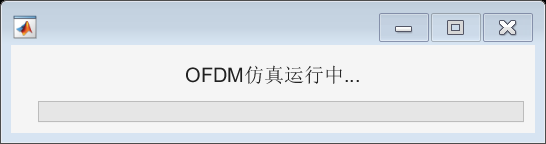

ofdm_waitbar = waitbar(0,"OFDM仿真运行中...");

% 每个信噪比仿真一次
for m = 1:length(EbN0_dB)
    % 每个传输的数据包都进行仿真
    for p = 1:packet_num
        rx_frame_buffer = []; % 设置接收缓冲区
        for u = 1:packet_size
            % 按帧提取信号
            tx_signal = tx_frame_buffer(((u - 1) * numel(ofdm_tx) + 1):u * numel(ofdm_tx));
            % 信号经过信道
            faded_signal = zeros(size(tx_signal)); % 衰落后的信号
            for i = 1:size(tx_signal,1)
                for j = 1:size(tx_signal,2)
                    faded_signal(i,j) = tx_signal(i,j) .* multipath_chan_impulse(i,j);
                end
            end
            
            % 高斯白噪声信道
            release(awgn_chan);
            power_dB(u) = 10 * log10(var(faded_signal));            % 计算发送端信号功率
            noise_var = 10 .^ (0.1 * (power_dB(u) - snr(m)));       % 用信噪比计算噪声功率
            rx_signal = awgn_chan(faded_signal,noise_var);          % 信号经过高斯白噪声信道
            
            % 信道均衡
            [equalize_signal,chan_est] = chan_equalizer(rx_signal,faded_signal,tx_signal,...
                ofdm_subframe_num,pilot_spacing);
            if EbN0_dB(m) == 5
                chan_est_15 = chan_est;
            end
            % OFDM解调
            rx_subframe = ofdm_demod(equalize_signal,cp_len,ofdm_subframe_num);    % OFDM解调
            rx_frame_buffer = [rx_frame_buffer';rx_subframe']';                    % 向缓冲区存储解调数据
        end
        % 去除保护间隔
        parallel_rx = rx_frame_buffer;
        parallel_rx((data_len / 2) + 1:(data_len / 2) + guard_size - 1,:) = []; % 去掉其他地方的保护间隔
        parallel_rx(1:1,:) = [];                                                % 去掉索引1处的保护间隔
        qam_rx_signal = reshape(parallel_rx,[numel(parallel_rx),1]);            % 并行数据转串行
        
        % 未编码数据的解调
        uncode_demod_signal = qamdemod(qam_rx_signal,mod_level,...
            'OutputType','bit','UnitAveragePower',true);                          % QAM解调
        uncode_data_out = randdeintrlv(uncode_demod_signal,intr_seed);            % 解交织
        uncode_data_out(numel(bin_data) + 1:end) = [];                            % 去除填充位
        uncode_err = uncode_error_rate(bin_data,uncode_data_out,0);               % 统计误码
      
        % 已编码数据的解调
        power_dB(u) = 10 * log10(var(qam_rx_signal));                   % 计算信号功率
        noise_var = 10 .^ (0.1 * (power_dB(u) - (EbN0_dB(m) + ...
            10 * log10(code_rate * k_bit) - 10 * log10(sqrt(data_len)))));  % 计算噪声功率
        code_demod_signal = qamdemod(qam_rx_signal,mod_level,'OutputType', ...
            'approxllr','UnitAveragePower',true,'NoiseVariance',noise_var); % QAM解调
        code_data_out = randdeintrlv(code_demod_signal,intr_seed);          % 解交织数据
        code_data_out(numel(bin_data) + 1:end) = [];                        % 去除填充位
        
        data_bits_out = []; % 译码输出结果
        data_out_buffer = code_data_out; % 译码缓冲区
        for q = 1:code_block_num
            data_bits_out = [data_bits_out;ldpcDecode(data_out_buffer(1:no_coded_bits),...
                ldpc_decoder_config,max_iter)];       % 数据译码并写入输出缓冲区
            data_out_buffer(1:no_coded_bits) = [];    % 删除已经译码的结果
        end
        data_bits_out = double(data_bits_out);                             % 转换为双精度
        code_err = code_error_rate(uncode_raw_data,data_bits_out,0);       % 收集误码结果
    end
    % 存储误码数据
    ofdm_err(m,:) = uncode_err;
    c_ofdm_err(m,:) = code_err;
    uncode_err = uncode_error_rate(bin_data,uncode_data_out,1);
    code_err = code_error_rate(uncode_raw_data,data_bits_out,1);

    waitbar(m / length(EbN0_dB),ofdm_waitbar); % 更新进度条
end
close(ofdm_waitbar); % 关闭进度条

% 多载波调制
frame_buffer = guardband_tx;
tx_frame_buffer = [];
for w = 1:packet_size
    otfs_tx = ISFFT(frame_buffer(:,1:ofdm_subframe_num));
    ofdm_tx = ofdm_mod(otfs_tx,N,cp_len,ofdm_subframe_num);
    frame_buffer(:, 1:ofdm_subframe_num) = [];
    tx_frame_buffer = [tx_frame_buffer;ofdm_tx];
end

otfs_waitbar = waitbar(0,"OTFS仿真运行中...");
for m = 1:length(EbN0_dB)

    for p = 1:packet_num
        rx_frame_buffer = [];

        for u = 1:packet_size

            tx_signal = tx_frame_buffer(((u - 1) * numel(ofdm_tx) + 1):u * numel(ofdm_tx));
            
            faded_signal = zeros(size(tx_signal));
            for i = 1:size(tx_signal,1)
                for j = 1:size(tx_signal,2)
                    faded_signal(i,j) = tx_signal(i,j) .* multipath_chan_impulse(i,j);
                end
            end
            
            release(awgn_chan);
            power_dB(u) = 10 * log10(var(faded_signal));
            noise_var = 10 .^ (0.1 * (power_dB(u) - snr(m)));
            rx_signal = awgn_chan(faded_signal,noise_var);
            
            equalize_signal = chan_equalizer(rx_signal,faded_signal,ofdm_subframe_num,pilot_spacing);
            
            otfs_rx = ofdm_demod(equalize_signal,cp_len,ofdm_subframe_num);
            rx_subframe = SFFT(otfs_rx);
            rx_frame_buffer = [rx_frame_buffer';rx_subframe']';
        end

        parallel_rx = rx_frame_buffer;
        parallel_rx((data_len / 2) + 1:(data_len / 2) + guard_size - 1,:) = [];
        parallel_rx(1:1,:) = [];
        qam_rx = reshape(parallel_rx,[numel(parallel_rx),1]);
        
        % 未编码
        uncode_demod_signal = qamdemod(qam_rx,mod_level,'OutputType','bit','UnitAveragePower',true);
        uncode_data_out = randdeintrlv(uncode_demod_signal,intr_seed);
        uncode_data_out(numel(bin_data) + 1:end) = [];
        uncode_err = uncode_error_rate(bin_data,uncode_data_out,0);
        % 已编码
        power_dB(u) = 10 * log10(var(qam_rx));
        noise_var = 10 .^ (0.1 * (power_dB(u) - (EbN0_dB(m) + 10 * log10(code_rate *...
            k_bit) - 10 * log10(sqrt(data_len)))));
        code_demod_signal = qamdemod(qam_rx,mod_level,'OutputType', 'approxllr','UnitAveragePower',true,'NoiseVariance',noise_var);
        code_data_out = randdeintrlv(code_demod_signal,intr_seed);
        code_data_out(numel(bin_data) + 1:end) = [];

        data_bits_out = [];
        data_out_buffer = code_data_out;
        for q = 1:code_block_num
            data_bits_out = [data_bits_out;ldpcDecode(data_out_buffer(1:no_coded_bits),...
                ldpc_decoder_config,max_iter)];
            data_out_buffer(1:no_coded_bits) = [];
        end
        data_bits_out = double(data_bits_out);
        code_err = code_error_rate(uncode_raw_data,data_bits_out,0);
        
    end
    otfs_err(m,:) = uncode_err;
    c_otfs_err(m,:) = code_err;
    uncode_err = uncode_error_rate(bin_data,uncode_data_out,1);
    code_err = code_error_rate(uncode_raw_data,data_bits_out,1);

    waitbar(m / length(EbN0_dB),otfs_waitbar); % 更新进度条
end
close(otfs_waitbar);

% 仿真一次更新一次场景，更新一次信道，计算一次通信与感知效率
% 此处书写仿真更新与通信感知逻辑
% scenario.advance; % 场景更新

## 结果绘图

% 绘图
figure;
semilogy(EbN0_dB,ofdm_err(:,1),'-g');
hold on;
semilogy(EbN0_dB,otfs_err(:,1),'-r');
semilogy(EbN0_dB,c_ofdm_err(:,1) + 1 / total_bits,'--g');
semilogy(EbN0_dB,c_otfs_err(:,1) + 1 / total_bits,'--r');
axis on
legend("OFDM","OTFS","C-OFDM","C-OTFS");
xlabel("Eb/N0"),ylabel("误码率");

legend(["OFDM", "OTFS", "C-OFDM", "C-OTFS"],...
    "Position", [0.1585 0.1428 0.1768, 0.1464])

xlim("auto")
ylim("auto")
% 信道响应绘图
figure;
mesh(1:281,0:63,abs(SFFT(raw_impulse)));
figure;
imagesc(1:281,0:63,abs(SFFT(raw_impulse)));
figure;
mesh(1:281,0:63,abs(SFFT(chan_est_15)'));
figure;
imagesc(1:281,0:63,abs(SFFT(chan_est_15)'));

## 结果保存

mat_filename = sprintf("%d_num_SNR_result",length(EbN0_dB));
save(mat_filename,"EbN0_dB","ofdm_err","c_ofdm_err","otfs_err","c_otfs_err",...
    "raw_impulse","chan_est_15","max_iter");